# D2Q9 Lattice Boltzmann Multicomponent

clc; clearvars; close all

## Parâmetros Gerais

**Número de direções **do conjunto de velocidades (D2Q9)

nlinks= 9; 

**Tempo de relaxamento** do sistema ($\tau$)

tau = 0.505;

**Quadrado** **da velocidade do som **($c_s^2$)

cssq = 1/3; 

**Viscosidade cinemática** no modelo Lattice Boltzmann ($\nu$)


$$\nu = c_s^2\left(\tau-\frac{1}{2}\right)$$


visc_LB = cssq*(tau-0.5); 

**Viscosidades dos componentes simulados** ($\nu_i$)


$$\nu_i = c_s^2\left(\tau_i-\frac{1}{2}\right)$$


visc1 = visc_LB; 
visc2 = visc_LB;

**Inverso da viscosidade** $\left(\frac{1}{\nu}\right)$


$$\frac{1}{\nu} = \frac{3}{\tau-\frac{1}{2}}$$


one_ov_nu = 1/visc_LB;

**Tempo de relaxamento** da difusão ($\tau_d$)

$\tau_d = \frac{D}{c_s^2} + \frac{1}{2}$, com $D$ sendo a difusividade

taud = 1; 

**Fator de relaxamento **($\omega$)


$$\omega = \frac{1}{\tau}$$


omega = 1/tau; 

**Nitidez da interface **entre os componentes simulados ($C_{\mathrm{sharp}}$)

sharp_c = 0.15*3;

**Tensão superficial **($\sigma$)

sigma = 0.1; 

**Dimensões da malha **($N_x$, $N_y$)

nx = 150;
ny = 150;

    **Passos de simulação** e **intervalo de amostragem**

nsteps = 10000; 
stamp = 10; 

**Forças externas** aplicadas (inexistentes já que são iguais a zero)

ggx = 0;
ggy = 0;

## Inicialização de Matrizes e Variáveis

**Matrizes**

f = zeros(nx,ny,9); % Matriz de funções de distribuição (9 direções no modelo D2Q9)
g = zeros(nx,ny,5); % Matriz de funções de fase (5 componentes, se aplicável)
rho = zeros(nx,ny); % Matriz de densidade, representando a densidade do fluido em cada célula
u = zeros(nx,ny); % Matriz de componente da velocidade na direção x
v = zeros(nx,ny); % Matriz de componente da velocidade na direção y
pxx = ones(nx,ny); % Matriz para armazenar a pressão normal na direção x
pyy = ones(nx,ny); % Matriz para armazenar a pressão normal na direção y
pxy = ones(nx,ny); % Matriz para armazenar a pressão de cisalhamento

fi = zeros(nx,ny); % Matriz do campo de fase atual
normx = zeros(nx,ny); % Matriz para armazenar a normal na direção x
normy = zeros(nx,ny); % Matriz para armazenar a normal na direção y
curvature = zeros(nx,ny); % Matriz para armazenar a curvatura do campo de fase
indicator = zeros(nx,ny); % Matriz indicadora para condições específicas do cálculo
bool_ind = zeros(nx,ny); % Matriz booleana para armazenamento de condições
ffx = zeros(nx,ny); % Matriz para componente da força na direção x
ffy = zeros(nx,ny); % Matriz para componente da força na direção y
grad_rho_x = zeros(nx,ny); % Matriz para armazenar o gradiente da densidade na direção x
grad_rho_y = zeros(nx,ny); % Matriz para armazenar o gradiente da densidade na direção y
mod_grad = zeros(nx,ny); % Matriz para armazenar a magnitude do gradiente da densidade

fneq = zeros(9,1); % Matriz para armazenar a distribuição de equilíbrio não uniforme
isfluid = zeros(nx,ny); % Matriz indicando se uma célula é fluida (1) ou não (0)

**Variáveis**

isfluid(2:nx-1,2:ny-1) = 1; % Define a condição fluida para todas as células internas
rho(:,:) = 1; % Inicializa a densidade para todas as células como 1

## Propriedades do Modelo

**Pesos de cada direção**


$$\begin{cases}
w_i  = \frac{4}{9} &&& \text{se } i=0 \\
w_i  = \frac{1}{9} &&& \text{se } i=1,2,3,4 \\
w_i  = \frac{1}{36} &&& \text{se } i=5,6,7,8 \\
\end{cases}$$


p = [4/9, ...
    1/9, 1/9, 1/9, 1/9, ...
    1/36, 1/36, 1/36, 1/36]; 

**Pesos misteriosos**


$$\begin{cases}
w_{g_i}  = \frac{2}{6} &&& \text{se } i=0 \\
w_{g_i}  = \frac{1}{6} &&& \text{se } i=1,2,3,4 \\
\end{cases}$$


p_g = [2/6, 1/6, 1/6, 1/6, 1/6];

**Direções opostas **(a partir do conjunto de velocidades)

opp = [1, 4, 5, 2, 3, 8, 9, 6, 7]; 

**Velocidades microscópicas**


$$\begin{cases}
c_i = (0,0) &&& \text{se } i=0 \\
c_i = (\pm 1,0), (0,\pm1) &&& \text{se } i=1,2,3,4 \\
c_i = (\pm 1,\pm 1) &&& \text{se } i=5,6,7,8 \\
\end{cases}$$


ex = [0, 1, 0, -1, 0, 1, -1, -1, 1]; 
ey = [0, 0, 1, 0, -1, 1, 1, -1, -1];

## **Cálculo da Função de Distribuição **($f_i$)** em Função da Distância Radial **($R_i$)

for ii=2:(nx-1)
    for jj=2:ny-1

        % Distância radial
        Ri=sqrt((ii-(nx/2))^2/2.^2+(jj-(ny/2))^2);

        % Cálculo da função de distribuição
        fi(ii,jj) = 0.5 + 0.5 * tanh(2*(20-Ri)/3);

    end
end

## Inicialização de Funções de Distribuição 

**Funções de distribuição **$f$

f(:,:,1)=p(1)*rho(:,:);
f(:,:,2)=p(2)*rho(:,:);
f(:,:,3)=p(2)*rho(:,:);
f(:,:,4)=p(2)*rho(:,:);
f(:,:,5)=p(2)*rho(:,:);
f(:,:,6)=p(6)*rho(:,:);
f(:,:,7)=p(6)*rho(:,:);
f(:,:,8)=p(6)*rho(:,:);
f(:,:,9)=p(6)*rho(:,:);

**Funções de distribuição** $g$

g(:,:,1)=p_g(1)*fi(:,:);
g(:,:,2)=p_g(2)*fi(:,:);
g(:,:,3)=p_g(2)*fi(:,:);
g(:,:,4)=p_g(2)*fi(:,:);
g(:,:,5)=p_g(2)*fi(:,:);

## Loop de Simulação

**Passos de tempo**

for tt=1:nsteps

**Cálculo do campo de fase **$f_i$ em relação ao campo $g$

    for ii=1:nx
        for jj=1:ny
            if(isfluid(ii,jj)==1)

                % Cálculo do campo de fase
                fi(ii,jj)=sum(g(ii,jj,:),3);

            end
        end 
    end

**Cálculo das normais e das matrizes**

    for ii=1:nx
        for jj=1:ny
            if(isfluid(ii,jj)==1)
                grad_fix=0;
                grad_fiy=0;
                for kk=1:9  

                    % Gradientes da função de campo de fase 
                    grad_fix=grad_fix+ 3*p(kk).*ex(kk).*((fi(ii+ex(kk),jj+ey(kk))));
                    grad_fiy=grad_fiy+ 3*p(kk).*ey(kk).*((fi(ii+ex(kk),jj+ey(kk))));

                end

                % Magnitude do gradiente
                mod_grad(ii,jj)=sqrt(grad_fix.^2+grad_fiy.^2);

                % Normalização dos gradientes
                normx(ii,jj)=grad_fix./(mod_grad(ii,jj)+10^-9);
                normy(ii,jj)=grad_fiy./(mod_grad(ii,jj)+10^-9);

                % Cálculo do indicador
                indicator(ii,jj)=sqrt(grad_fix.^2+grad_fiy.^2);

            end
        end
    end

**Cálculo da curvatura e das forças de tensão superficial**

    for ii=1:nx
        for jj=1:ny
            if(isfluid(ii,jj)==1)

                % Curvatura
                 curvature(ii,jj)=0;
                     for kk=1:9
                        curvature(ii,jj)=curvature(ii,jj) - 3.*p(kk).*(ex(kk).*(normx(ii+ex(kk),jj+ey(kk))) + ...
                                                                       ey(kk).*(normy(ii+ex(kk),jj+ey(kk))));
                     end 

                 % Forças de tensão superficial
                 ffx(ii,jj)=sigma.*curvature(ii,jj).*normx(ii,jj).*indicator(ii,jj) ;
                 ffy(ii,jj)=sigma.*curvature(ii,jj).*normy(ii,jj).*indicator(ii,jj) ;

            end
        end
    end

**Cálculo dos momentos**

    for ii=1:nx
        for jj=1:ny
            if(isfluid(ii,jj)==1)

                % Cálculo das velocidades
                u(ii,jj)=(f(ii,jj,2)-f(ii,jj,4)+f(ii,jj,6)-f(ii,jj,7)-f(ii,jj,8)+f(ii,jj,9))./rho(ii,jj) + ffx(ii,jj)*0.5./rho(ii,jj) ;
                v(ii,jj)=(f(ii,jj,3)-f(ii,jj,5)+f(ii,jj,6)+f(ii,jj,7)-f(ii,jj,8)-f(ii,jj,9))./rho(ii,jj) + ffy(ii,jj)*0.5./rho(ii,jj) ;   
                uu=0.5*(u(ii,jj).^2+v(ii,jj).^2)/cssq;

                % Cálculo da densidade
                rho(ii,jj)=sum(f(ii,jj,:),3) ; 

                % Cálculo dos momentos
                for kk=1:9
                    udotc=(u(ii,jj)*ex(kk) + v(ii,jj)*ey(kk))/cssq;
                    
                    % Cálculo de HeF
                    HeF=(p(kk)*(rho(ii,jj) + rho(ii,jj).*(udotc + 0.5.*udotc.^2 - uu))).*((ex(kk)-u(ii,jj)).*ffx(ii,jj) + (ey(kk)-v(ii,jj)).*ffy(ii,jj))./(rho(ii,jj).*cssq);
                    
                    % Distribuição de equilíbrio
                    feq=p(kk)*(rho(ii,jj) + rho(ii,jj).*(udotc + 0.5.*udotc.^2 - uu)) - 0.5.*(HeF);
                    fneq(kk)=f(ii,jj,kk)- feq;
                end

                % Cálculo de momentos
                pxx(ii,jj)= fneq(2) + fneq(4) + fneq(6) + fneq(7) + fneq(8) + fneq(9);
                pyy(ii,jj)= fneq(3) + fneq(5) + fneq(6) + fneq(7) + fneq(8) + fneq(9);
                pxy(ii,jj)= fneq(6) - fneq(7) + fneq(8) - fneq(9); 

            end
        end 
    end

**Cálculo da colisão**

    for ii=1:nx
        for jj=1:ny
            if(isfluid(ii,jj)==1)

                % Cálculo da energia cinética média
                 uu=0.5*(u(ii,jj).^2+v(ii,jj).^2)/cssq;

                 for kk=1:9                        

                    % Produto escalar da velocidade do fluido e da direção da partícula
                    udotc=(u(ii,jj)*ex(kk) + v(ii,jj)*ey(kk))/cssq;

                    % Cálculo da função de distribuição de equilíbrio
                    feq=p(kk)*(rho(ii,jj) + rho(ii,jj).*(udotc + 0.5.*udotc.^2 - uu));
                     
                    % Cálculo de HeF (forças externas ou tensão superficial)
                    HeF=0.5.*(p(kk)*(rho(ii,jj) + rho(ii,jj).*(udotc + 0.5.*udotc.^2 - uu))).*((ex(kk)-u(ii,jj)).*ffx(ii,jj) + (ey(kk)-v(ii,jj)).*ffy(ii,jj))./(rho(ii,jj).*cssq);
                    
                    % Cálculo da diferença em relação à função de equilíbrio
                    fneq=(ex(kk).*ex(kk)-cssq)*pxx(ii,jj)+(ey(kk).*ey(kk)-cssq)*pyy(ii,jj) ...
                         + 2*ex(kk).*ey(kk).*pxy(ii,jj);

                    % Cálculo da diferença em relação à função de equilíbrio
                    f(ii+ex(kk),jj+ey(kk),kk)=feq + (1.0-omega)*(p(kk)/(2*cssq^2))*fneq  + HeF  ;%+guoGrad
                     
                 end

                for kk=1:5

                    % Produto escalar da velocidade do fluido e da direção da partícula
                    udotc=(u(ii,jj)*ex(kk) + v(ii,jj)*ey(kk))/cssq;

                     % Cálculo da função de distribuição de equilíbrio para o segundo componente
                    feq=p_g(kk).*fi(ii,jj).*(1 + udotc);
                     
                    % Correção envolvendo a fase e a normal
                    Hi=sharp_c.*fi(ii,jj).*(1-fi(ii,jj)).*(ex(kk).*normx(ii,jj)+ ey(kk).*normy(ii,jj));%.*bool_ind(ii,jj);
                    
                    % Atualização da função de distribuição para o segundo componente
                    g(ii,jj,kk)=feq + p_g(kk).*Hi ;

                end
                 
            end
        end
    end

    % Realiza a mudança de posição das funções de distribuição para simular movimento
    for kk=1:5
        g(:,:,kk)=circshift(g(:,:,kk), [ex(kk),ey(kk),0]);
    end

**Condições de contorno**

    for ii=1:nx
        for jj=1:ny
            if(isfluid(ii,jj)==0)
                for kk=1:9
                    if(ii+ex(kk)>0 && jj+ey(kk)>0)

                        % Atualiza a função de distribuição de partículas
                        f(ii+ex(kk),jj+ey(kk),kk)=rho(ii,jj).*p(kk);

                    end
                end
                for kk=1:5
                    if(ii+ex(kk)>0 && jj+ey(kk)>0)

                        % Atualiza a função de distribuição para o segundo componente
                        g(ii+ex(kk),jj+ey(kk),kk)=fi(ii,jj).*p_g(kk);

                    end
                end
                
            end
        end
    end

    % Condições de contorno nos limites da malha
    fi(:,1)=fi(:,2); 
    fi(:,ny)=fi(:,ny-1); 
    fi(1,:)=fi(2,:); 
    fi(nx,:)=fi(nx-1,:); 

**Exibição periódica dos resultados**

    if(mod(tt,100)==0)      
        imagesc(fi')
        axis xy
        axis equal
        colorbar
        drawnow;
    end

**Exibe os passos**

    disp(tt)

**Fim do loop de simulação**

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31

    32

    33

    34

    35

    36

    37

    38

    39

    40

    41

    42

    43

    44

    45

    46

    47

    48

    49

    50

    51

    52

    53

    54

    55

    56

    57

    58

    59

    60

    61

    62

    63

    64

    65

    66

    67

    68

    69

    70

    71

    72

    73

    74

    75

    76

    77

    78

    79

    80

    81

    82

    83

    84

    85

    86

    87

    88

    89

    90

    91

    92

    93

    94

    95

    96

    97

    98

    99

   100

   101

   102

   103

   104

   105

   106

   107

   108

   109

   110

   111

   112

   113

   114

   115

   116

   117

   118

   119

   120

   121

   122

   123

   124

   125



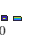

   300

   301

   302

   303

   304

   305

   306

   307

   308

   309

   310

   311

   312

   313

   314

   315

   316

   317

   318

   319

   320

   321

   322

   323

   324

   325

   326

   327

   328

   329

   330

   331

   332

   333

   334

   335

   336

   337

   338

   339

   340

   341

   342

   343

   344

   345

   346

   347

   348

   349

   350

   351

   352

   353

   354

   355

   356

   357

   358

   359

   360

   361

   362

   363

   364

   365

   366

   367

   368

   369

   370

   371

   372

   373

   374

   375

   376

   377

   378

   379

   380

   381

   382

   383

   384

   385

   386

   387

   388

   389

   390

   391



end